# Hands-on note : PARCHG_gen 

## 测试例子与教程

可以使用 运行节 来局部运行

### BHZ-HODSM model

#### 导入数据

load('BHZ-HODSM-PARCHG-test.mat');

- 暂时忽略 Atom_name Atom_num Rm sites 这四个变量 这些变量可以读取POSCAR得到

注意两个关键变量 **WaveFunc orb_list**

- **orb_list  **就是按顺序排好的轨道位置 注意 **分数化坐标**

- **WaveFunc **可以取多列, 每列一个vector表征一个本征态 

-                    这里我们就取VBM和CBM两个能级的波函数 实际上应该取 VBM-1:CBM+1四个能级 这里我们简化一下

#### Glance_mode

我们可以用matlab先画出来瞅瞅

- 首先 copy POSCAR_HODSM 变成 POSCAR

copyfile('POSCAR_HODSM','POSCAR');

- 直接使用 PARCHG_gen_wire(orb_list,WaveFunc) 即可在Matlab中查看

- 注意这里的隐形输入实际上是 POSCAR这个文件 他提供了 晶格常数等信息

PARCHG_gen_wire(orb_list,WaveFunc);

这并不是一个好的演示数据 过于庞大 不过也可以看出程序比较Robust

我们可以把实时脚本的图窗在外部打开，这样可以转动去看

- 我们引入 Ncycle 这个变量 这样可以展现一个层状结构 会很卡 

% Ncycle = 3;
% PARCHG_gen_wire(orb_list,WaveFunc,Ncycle);

#### PARCHG_mode

我们可以把他输出成 PARCHG的形式

- R_cutoff 原子半径 取 1 或者 0.53 在这在个范围内的电子密度为定值

- PARCHG_file 文件名

需要跑一阵

R_cutoff = 1; %0.53
PARCHG_file = 'PARCHG.HODSM.vasp';
PARCHG_gen_wire(orb_list,WaveFunc,R_cutoff,PARCHG_file);

我们可以直接在vesta打开这个 文件

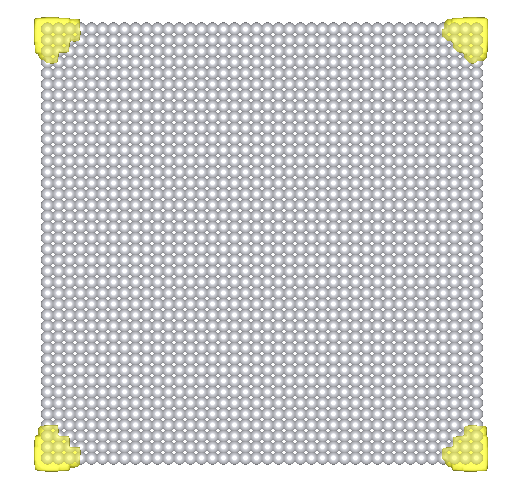

目前可以用三种方法调控效果 

- 在vesta中调整 isosurface

- 选取不同的 R_cutoff ,对于二维材料 C方向的真空层稍微大点

- 一个额外的参数 curve_R 

curve_R 是一个 默认为 [0.2 0.2 0.2 ] 的向量 它标定三个方向 电子密度的像素大小

比如[1 1 1] 结果就会粗糙 运行会快 PARCHG文件小

[0.1 0.1 0.1] 结果就会精细 运行就会慢 PARCHG 文件大

curve_R = [1 1 1]; 
PARCHG_gen_wire(orb_list,WaveFunc,R_cutoff,PARCHG_file,curve_R);

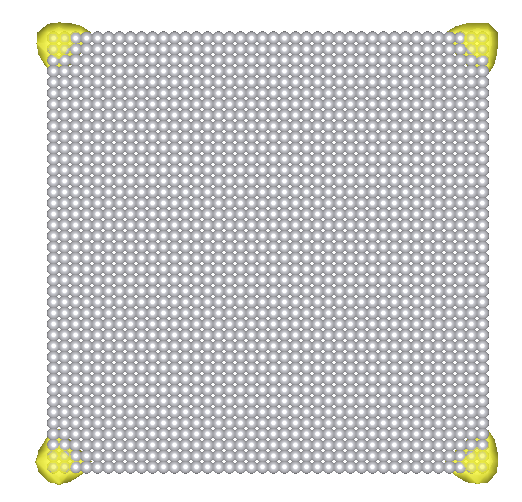

% curve_R = [0.1 .1 .1]; 
% PARCHG_gen_wire(orb_list,WaveFunc,R_cutoff,PARCHG_file,curve_R);

事实上我们有个读取POSCAR的函数 

文件夹内的 elements.txt 有用

% [Rm,sites,Atom_name,Atom_num,~]=POSCAR_readin('POSCAR','vasp');

完整的输入应该是

% PARCHG_gen_wire(orb_list,WaveFunc,R_cutoff,PARCHG_file,curve_R,Rm,sites,Atom_name,Atom_num );

#### PARCHG.cif_mode

我们可以用原子的大小种类来替换电子密度分布

使用另一个函数 PARCHG_gen_atom

这个程序在使用过程中可能会因为matlab版本问题 没有normalize这个函数 可以问我要

load('BHZ-HODSM-PARCHG-test.mat');
copyfile('POSCAR_HODSM','POSCAR');
[Rm,~,~,~,element_table]=POSCAR_readin('POSCAR','vasp');

这里我们需要用到元素周期表

同时在输入中加了一个 HIST

HIST 大概意思就是 我要用  HIST+1 种原子进行区分

HIST = 2; % 2 element 
PARCHG_file = 'PARCHG.HODSM.cif';
PARCHG_gen_atom(orb_list,WaveFunc,PARCHG_file,HIST,Rm,element_table);

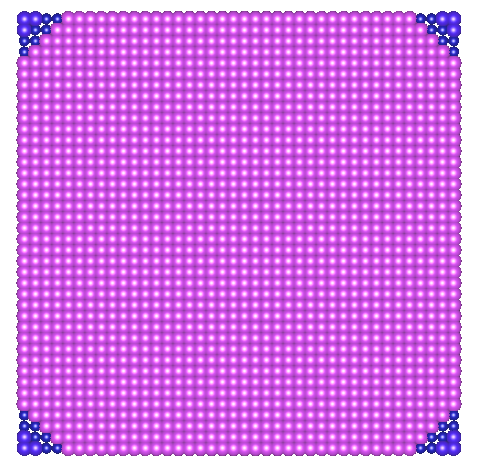

- 颜色 大小 就在vesta中自己调试即可

支持简化运行

% PARCHG_gen_atom(orb_list,WaveFunc,PARCHG_file,HIST);

## 点我，直接跳到 GDY例子

clear;

### 读取并处理输入数据

#### 读取POSCAR

这里给的poscar还是应该按照poscar的格式 (分数化坐标)

我生成了一个 10*10*1 的 GDY POSCAR 

POSCAR扩胞程序可以向我索取 或用vesta

copyfile('POSCAR_GDY_supercell','POSCAR');
[Rm,sites,Atom_name,Atom_num,element_table]=POSCAR_readin('POSCAR','vasp');

#### 读取WaveFunc orb_list

GDY_phon_DATA = importdata('crystal-projection');

WaveFunc

WaveFunc = GDY_phon_DATA(:,2);

orb_list

orb_list_car = GDY_phon_DATA(:,3:5);

转化成分数化坐标

orb_list = orb_list_car/Rm;

### Glance mode

PARCHG_gen_wire(orb_list,WaveFunc);

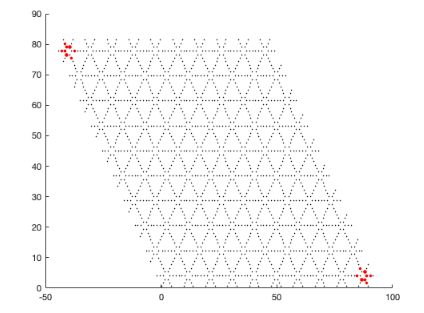

### PARCHG mode

R_cutoff = 0.53; %0.53
PARCHG_file = 'PARCHG.GDY.vasp';
PARCHG_gen_wire(orb_list,WaveFunc,R_cutoff,PARCHG_file);

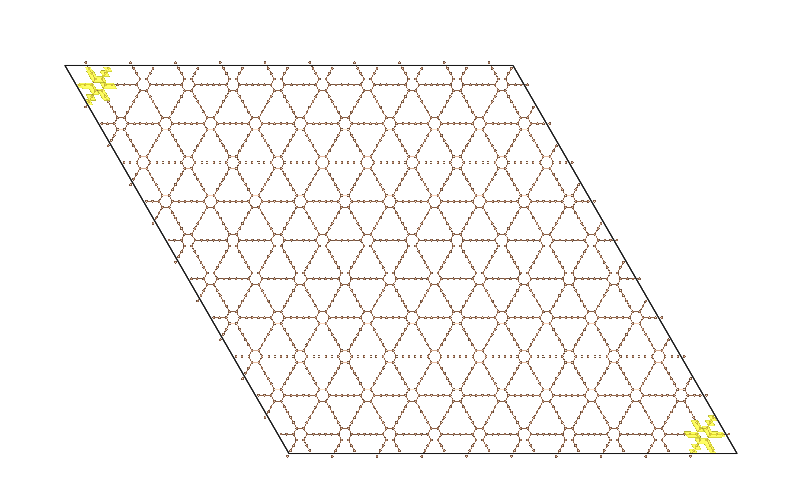

### PARCHG.cif mode

#### 稍微放大一下wavefunc 

WaveFunc = WaveFunc*100;
HIST = 2; % 3 element 
PARCHG_file = 'PARCHG.GDY.cif';
PARCHG_gen_atom(orb_list,WaveFunc,PARCHG_file,HIST,Rm,element_table);